LTR配置输出状态反馈

输入：被控系统，Tc = 控制常数，To = 观测常数， To \approx Tc/3

输出：状态反馈增益F 观测增益K  被控系统使用输出状态反馈后的闭环系统BF 该BF的静态前馈校正系数Precomp_stat

[LTR（回路传递恢复）与前置补偿器 - 知乎 (zhihu.com)](https://zhuanlan.zhihu.com/p/279994954)

function [F,K,BF,precomp_stat] = LTR(sys, Tc, To)
s = tf('s');
if (class(sys) == "tf") || (class(sys) == "ss")
    [A,B,C,D] = ssdata(sys);
    if rank(ctrb(A,B))~=length(A)||rank(obsv(A,C))~=length(A)
        disp('Sys not controllable or not observable')
        disp('Try another way')
        return
    end
else
    disp('sys should be a transfer-function or a state-space model!')
    return
end


Cible

[num,den]=ss2tf(A,B,ones(size(C)),D);
Gc=tf(num,den); %cible

poles = pole(Gc);


for i = find(poles>0)
    poles(i)=-poles(i);
end


poles_desired = [];
for ct = 1: 1 : length(poles)
    if (real(poles(ct))>-1/Tc)
        poles_desired = [poles_desired;-1/Tc+1*imag(poles(ct))* sqrt(-1)];
    else
        poles_desired = [poles_desired;poles(ct)];
    end
end

F = acker(A,B,poles_desired) ;

Restauration

% G = tf of controlled system
if class(sys)=="tf"
    G = sys;
else
    [n,d] = ss2tf(A,B,C,D);
    G = tf(n,d);
end

poles = pole(G);
zeros = zero(G);

for i = find(zeros>0)
    zeros(i)=-zeros(i);
end

pole_ob=[];
for j = 1 : length(zeros)
    pole_ob = [pole_ob; zeros(j)];
end
for j = 1 : length(poles)-length(zeros)
    pole_ob = [pole_ob;-1/To];
end

K = acker(A.',C.',pole_ob).';


最终闭环传递函数

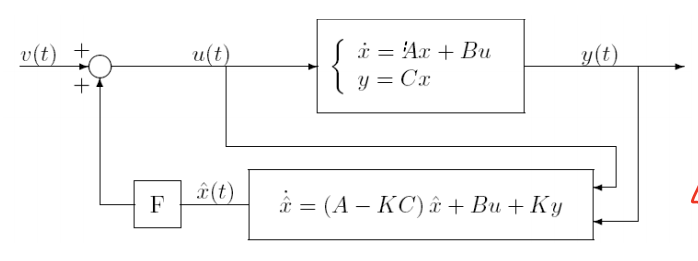

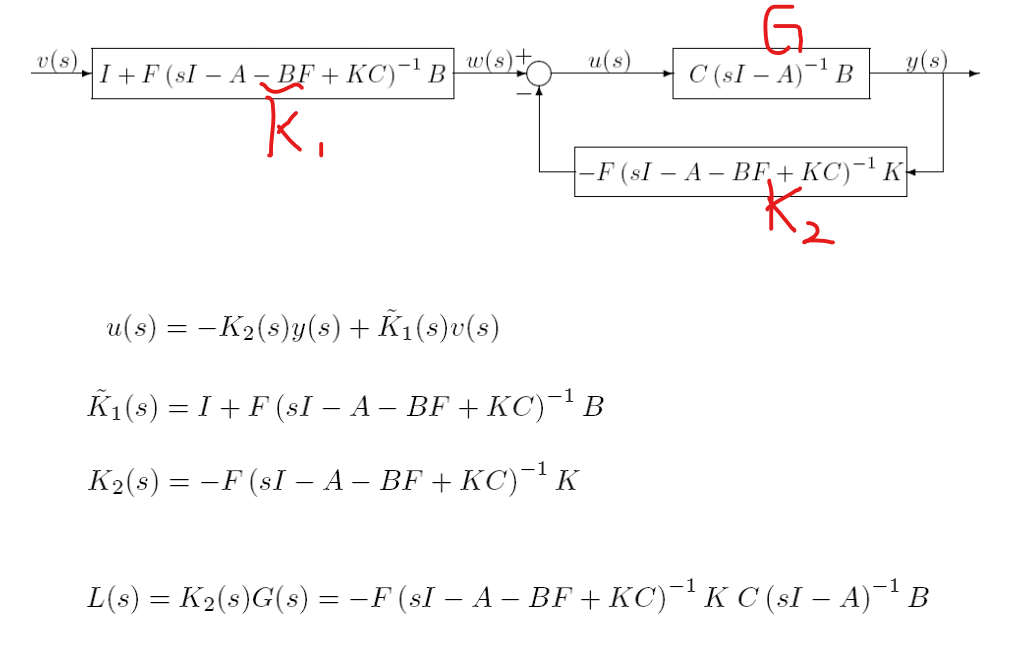

% 方法1：最麻烦的，算出来的结果最不准
% [num,den] = ss2tf(A-B*F-K*C,K,-(-F),D); % regulateur
% K2 = tf(num,den);
% L = G*tf(num,den);
% 
% [num,den] = ss2tf(A-B*F-K*C,B,-F,D);
% K1tilde = 1 + tf(num,den);
% 
% BF = K1tilde*G/(1+L);

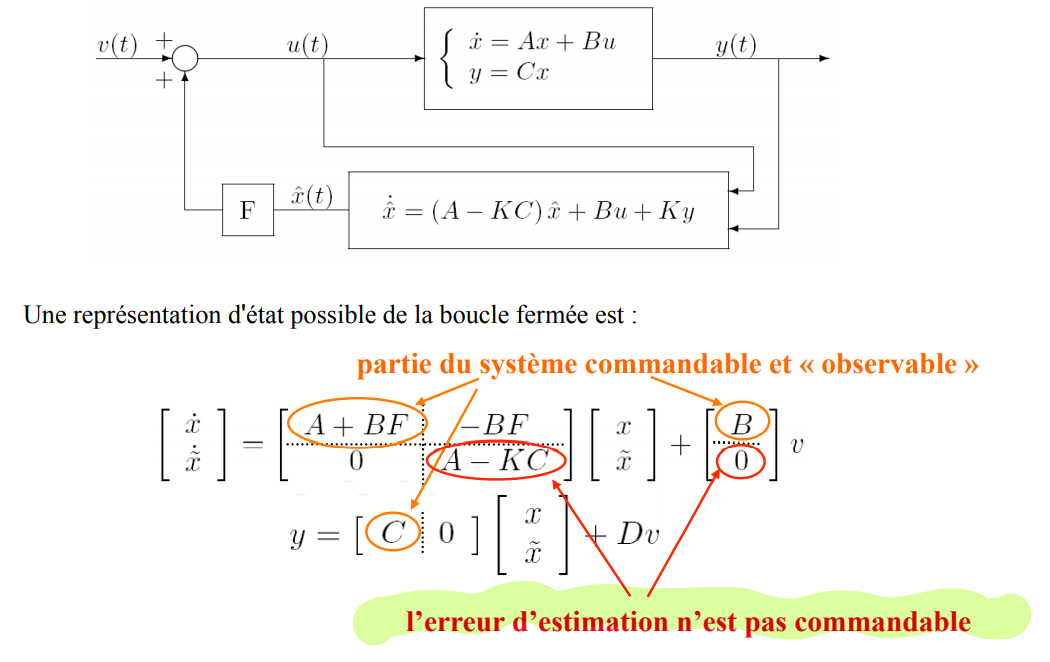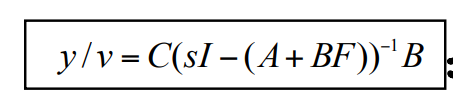

% 方法2：也很麻烦的，结果次不准
% BF = C*(s*eye(length(A))-(A-B*F))^(-1)*B;

 

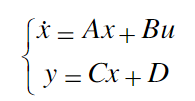----->

% 方法3：最准
[num,den]=ss2tf(A-B*F,B,C,D);
BF = tf(num,den);
BF = Cleantf(BF);

l = length(BF.Denominator{1}); %长度 最后一位
precomp_stat = BF.Denominator{1}(l)/BF.Numerator{1}(l); %分子分母系数的最后一位之比即是终值，取倒数得到gain


figure()
hold on
step(G)
step(BF)
step(precomp_stat*BF)
legend('sys','BF after LTR','BF with Precomp stat')


end